% Read the whole file as strings
lines = readlines("C:\Users\admin\Desktop\CylinderRust\Data.txt");

% Find the lines where "DNA" and "Particles start" are mentioned
dna_start = find(lines == "DNA") + 1;
particles_start = find(lines == "Particles start") + 1;

% Extract the DNA lines
dna_lines = lines(dna_start : (particles_start - 2)); % until the line before "Particles start"
dna_data = sscanf(join(dna_lines, newline), '%f,%f,%f,%f,%f,%f');
DNA = reshape(dna_data, 6, []).';  % Nx6 matrix: [x y z dx dy dz]
if size(DNA, 2) ~= 6
    DNA = reshape(DNA, [], 6);  % Force 6 columns
end

% Extract the particle lines
particle_lines = lines(particles_start : end);
particle_data = sscanf(join(particle_lines), '%f,%f,%f\n');
Particles = reshape(particle_data, 3, []).';  % Mx3 matrix: [x y z]

% Plotting parameters
figure;
hold on;
axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
xlim([0 1]); ylim([0 1]); zlim([0 1]);
grid on;
view(3);

% Plot cube boundaries (optional wireframe)
plot3([0 1 1 0 0 0 1 1 0 0 0 1 1 1 0 0], ...
      [0 0 1 1 0 0 0 1 1 0 0 0 0 1 1 1], ...
      [0 0 0 0 0 1 1 1 1 1 0 0 1 1 1 0], 'k:');
linspacet = 5;
linspacetotal = 100;
% Plot the DNA lines
DNA_size = 0

DNA_size = 0

for i = 1:size(DNA, 1)
    point = DNA(i, 1:3);
    direction = DNA(i, 4:6);

    t = linspace(-linspacet, linspacet, linspacetotal);
    line_pts = point + t' .* direction;

    in_bounds = all(line_pts >= 0 & line_pts <= 1, 2);
    line_pts = line_pts(in_bounds, :);

    DNA_size = DNA_size + size(line_pts,1) * linspacet*2/linspacetotal * sqrt(direction(1)^2+direction(2)^2+direction(3)^2)/2;

    plot3(line_pts(:,1), line_pts(:,2), line_pts(:,3), 'b', 'LineWidth', 2)
end

DNA_size

DNA_size = 0.6000

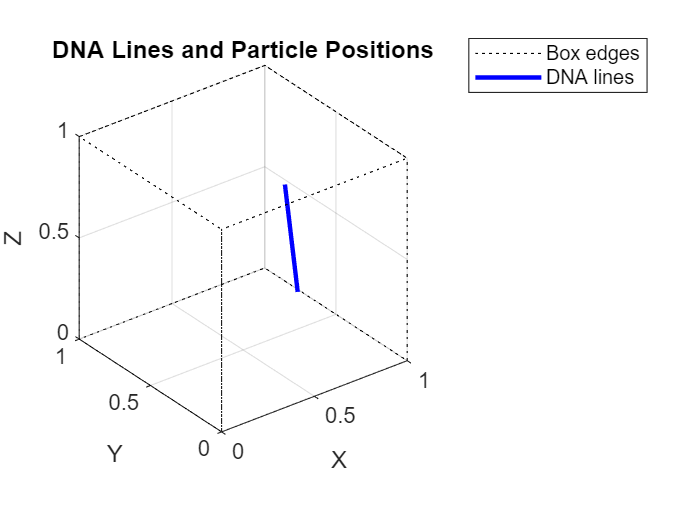

% Plot the particles
%scatter3(Particles(:,1), Particles(:,2), Particles(:,3), 20, 'r', 'filled');
hold off
title('DNA Lines and Particle Positions');
legend('Box edges', 'DNA lines', 'Particles');


% Import the data
TTDmatrix = readmatrix("C:\Users\admin\Desktop\CylinderRust\TTD.txt");

height = size(TTDmatrix, 1)

height = 1

width = size(TTDmatrix,2)

width = 10000

TTDx = linspace(0,width,width);
TTDx = TTDx(2:end);

% Constants
deltax = 1/200;
deltay = 1/200;
deltaz = 1/200;
D_3d = (deltax^2 + deltay^2 + deltaz^2) / 6; %Skal justeres med 3d.
r_int = 0.05;
V = 1;
N = 1;
n = 1;
sigma = deltax;
P_onns = 0.05;
k_nson = 2 * pi * r_int * P_onns * sigma / sqrt(2 * pi);
l_dna = DNA_size / V; %N / B^3 eller volumen af linjestykker.
%Find længde. 

% Inverse Laplace Transform using Talbot method
K0 = @(s) besselk(0, sqrt(s / D_3d) * r_int);
K1 = @(s) besselk(1, sqrt(s / D_3d) * r_int);
K_1_div_K_0 = @(s) K1(s) ./ K0(s);

W_bulk_cyl = @(q, s) (1 + (2 * pi * D_3d .* sqrt(q.^2 + s ./ D_3d) .* r_int .* besselk(1, r_int .* sqrt(q.^2 + s ./ D_3d))) ./ ...
                      (k_nson .* besselk(0, r_int .* sqrt(q.^2 + s ./ D_3d))) ).^(-1);

FourierInverse = @(s, r) integral(@(q) (sin(q .* r) ./ (q .* r)) .* W_bulk_cyl(q, s) .* q.^2, 0, 50, 'ArrayValued', true);

J_cap = @(s) FourierInverse(s, 0.05);  

%J_cap = @(s) k_nson * l_dna /(n * s^2) * (1+k_nson * K0(s) /(2 * pi * sqrt(s *D_3d) * r_int * K1(s)))^(-1) This equation should be used for non-releasing systems.


TalbotInverse = @(t) Talbot(J_cap, t, 8);
TalbotInverse_array = arrayfun(TalbotInverse,TTDx);

P_survival = TalbotInverse_array

P_survival =   292.1612  194.6782  151.4283  125.6402  108.0540   95.0920   85.0400   76.9600   70.2896   64.6682   59.8526   55.6719   52.0020   48.7503   45.8461   43.2343   40.8715   38.7225   36.7588   34.9570   33.2975   31.7638   30.3422   29.0207   27.7890   26.6385   25.5614   24.5510   23.6014   22.7075   21.8645   21.0684   20.3156   19.6027   18.9267   18.2851   17.6753   17.0952   16.5428   16.0163   15.5140   15.0344   14.5760   14.1377   13.7182   13.3164   12.9313   12.5620   12.2076   11.8673


P_survival = exp(-TalbotInverse_array).^N

P_survival =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


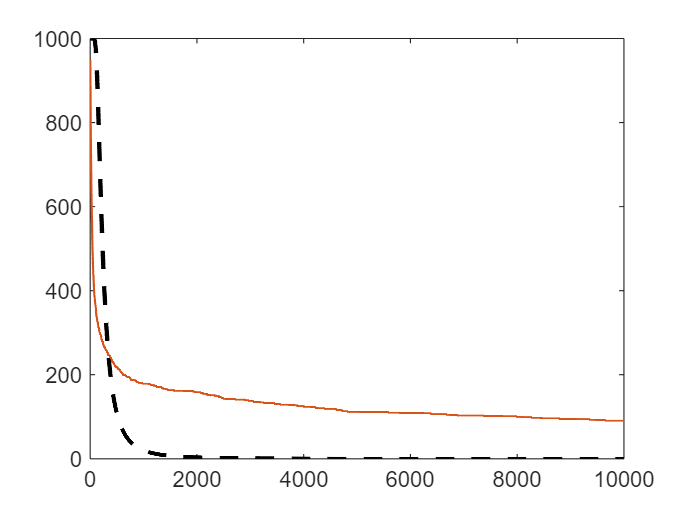


%P_survival_values = arrayfun(P_survival,TTDx);

figure();
plot(TTDx,(1000-P_survival * 1000), color='black', LineStyle="--", LineWidth=2);
hold on
for i = 1:height
TTD = TTDmatrix(i,2:end);
plot(TTDx,(1000-TTD), LineWidth=1);
end
hold off